# Actividad Práctica N°2: Diseño de controladores en variables de estado en tiempo continuo

## Caso de estudio 1. Sistema de tres variables de estado

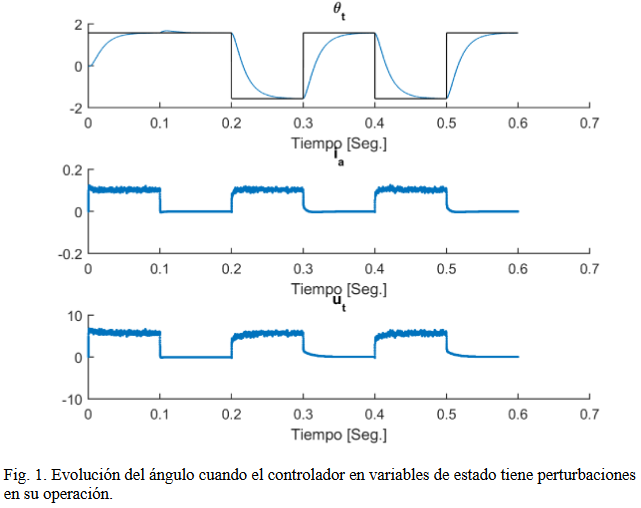

Dadas las ecuaciones del motor de corriente continua con torque de carga $T_L$ no nulo, con los parámetros:

- 
$$L_{\textrm{AA}} =5\;{10}^{-3}$$


- 
$$J=0\ldotp 004$$


- 
$$R_A =0\ldotp 2$$


- 
$$B_m =0\ldotp 005$$


- 
$$K_i =6\ldotp 5\;{10}^{-5}$$


- 
$$K_m =0\ldotp 055$$



$$\frac{{\textrm{di}}_a }{\textrm{dt}}=-\frac{R_A \;}{L_{\textrm{AA}} }i_a -\frac{K_m \;}{L_{\textrm{AA}} }\omega {\;}_r +\frac{1\;}{L_{\textrm{AA}} }v_a$$



$$\frac{d\omega {\;}_r }{\textrm{dt}}=\frac{K_i \;}{J}i_a -\frac{B_m \;}{J}\omega_r -\frac{1\;}{J}T_L$$



$$\frac{d\theta {\;}_t }{\textrm{dt}}=\omega_r$$


- Implementar un sistema en variables de estado que controle el ángulo del motor, para consignas de $\frac{\pi }{2}$ y $-\frac{\pi }{2}$ cambiando cada 2 segundos y que el $T_L$ de $1\ldotp 15\;10{\;}^{-3}$ aparece sólo para $\frac{\pi }{2}$ y para $-\frac{\pi }{2}$ es nulo. Hallar el valor de integración de Euler adecuado. El objetivo es mejorar la dinámica del controlador que muestra la Fig. 1.

- Considerar que no puede medirse la corriente y sólo pueda medirse el ángulo, por lo que debe implementarse un observador. Obtener la simulación en las mismas condiciones que en el punto anterior, y superponer las gráficas para comparar.

Primero se comienza definiendo las variables a utilizar:

Laa = 5e-3;
J = 0.004;
Ra = 0.2;
Bm = 0.005;
Ki = 6.5e-5;
Km = 0.055;

Ahora la representación matricial en variables de estado:

A = [-Ra/Laa -Km/Laa 0; Ki/J -Bm/J 0; 0 1 0]

A =   -40.0000  -11.0000         0
    0.0162   -1.2500         0
         0    1.0000         0


B = [1/Laa 0; 0 -1/J; 0 0]

B =    200     0
     0  -250
     0     0


La matriz C tiene la siguiente forma, de modo de poder 

C = [0 0 1]

C =      0     0     1


D = [0 0]

D =      0     0


Se obtiene la función de transferencia para el torque:

sys = ss(A,B,C,D)

sys =
 
  A = 
            x1
   x1      -40
   x2  0.01625
   x3        0
 
            x2
   x1      -11
   x2    -1.25
   x3        1
 
            x3
   x1        0
   x2        0
   x3        0
 
  B = 
         u1    u2
   x1   200     0
   x2     0  -250
   x3     0     0
 
  C = 
       x1  x2  x3
   y1   0   0   1
 
  D = 
       u1  u2
   y1   0   0
 
Continuous-time state-space model.



GTheta = tf(sys)

GTheta =
 
  From input 1 to output:
               
           3.25
               
  ----------------------
                        
  s^3 + 41.25 s^2       
                        
               + 50.18 s
                        
 
  From input 2 to output:
                   
      -250 s - 1e04
                   
  ----------------------
                        
  s^3 + 41.25 s^2       
                        
               + 50.18 s
                        
 
Continuous-time transfer function.



Se puede ver que la función de transferencia está dada en forma de matriz, ya que se está ante un sistema del tipo MIMO, es decir, el resultado obtenido tiene sentido hasta ahora.

Ahora, para controlar al sistema se utiliza un diseño con LQR. Para ello es necesario primero declarar las variables Q, R y las matrices ampliadas.

Q = diag([0.1 0.1 0.1 100000])

Q = 	1.0e+05 *

    0.0000         0         0         0
         0    0.0000         0         0
         0         0    0.0000         0
         0         0         0    1.0000


R = 100;
Aamp = [A zeros(3,1); -C 0]

Aamp =   -40.0000  -11.0000         0         0
    0.0162   -1.2500         0         0
         0    1.0000         0         0
         0         0   -1.0000         0


Bamp = [B(:,1); 0]

Bamp =    200
     0
     0
     0


K = lqr(Aamp,Bamp,Q,R)

K =     0.0116   23.2442   50.0305  -31.6228


Ahora, para calcular el tiempo de integración para Euler es necesario obtener los polos a lazo cerrado, y trabajar con la dinámica del más rápido. Los polos son:

poles = eig(Aamp-Bamp(:,1)*K)

poles =  -40.4924 + 0.0000i
  -1.5997 + 0.0000i
  -0.7396 + 1.0196i
  -0.7396 - 1.0196i


El polo más rápido es:

lambda = max(poles)

lambda = -40.4924

Entonces, se calcula $t_r$, de modo de simular con un tiempo menor al mismo.

tr = log(0.95)/lambda

tr = 0.0013

Se decide entonces, utilizar un período de integración para Euler de $1\;{10}^{-4}$.

h = 1e-4;
simTime = 50;
t = 0:h:(simTime-h);

Con estas variables, se define la entrada, llamada reference.

reference = (pi/2)*square(2*pi*(1/50)*t);

La señal de referencia es la siguiente:

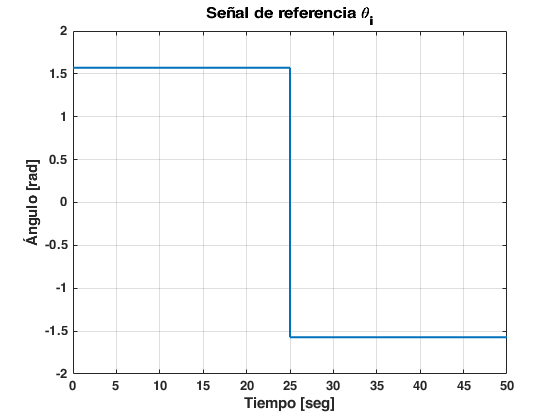

plot(t,reference,'LineWidth',1.5)
xlabel('Tiempo [seg]')
ylabel('Ángulo [rad]')
title('Señal de referencia \theta_i')
grid

El torque de entrada del sistema es:

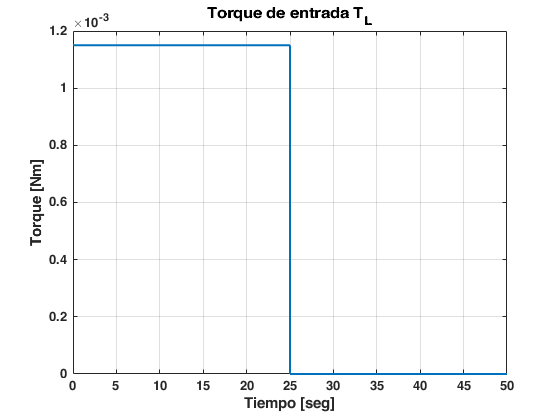

torque = ((1.15e-3)/2)*square(2*pi*(1/50)*t)+((1.15e-3)/2);
plot(t,torque,'LineWidth',1.5)
xlabel('Tiempo [seg]')
ylabel('Torque [Nm]')
title('Torque de entrada T_L')
grid

Las condiciones iniciales del sistema son nulas, para ello se plantean las siguientes variables:

ia(1) = 0;
theta(1) = 0;
omega(1) = 0;

El vector de estados del sistema está dado por:

stateVector = [ia(1) omega(1) theta(1)]';

El punto de operación se lo toma alrededor del origen, y, luego, se plantea el vector x, propio de la representación en variables de estado.

xop = [0 0 0]';
x = [ia(1) omega(1) theta(1)];
zeta(1) = 0;
integ(1) = zeta(1);

Ahora, la simulación propiamente dicha:

for i = 1:simTime/h
    zetaP = reference(i)-C*stateVector;
    zeta(i) = integ+zetaP*h;
    u(i) = -K(1:3)*stateVector-K(4)*zeta(i);
    ia(i) = x(1);
    omega(i) = x(2);
    theta(i) = x(3);
    x1P = -Ra*x(1)/Laa-Km*x(2)/Laa+u(i)/Laa;
    x2P = Ki*x(1)/J-Bm*x(2)/J-torque(i)/J;
    x3P = x(2);
    xP = [x1P x2P x3P]';
    x = x+h*xP;
    stateVector = [ia(i) omega(i) theta(i)]';
    integ = zeta(i);
end

Ahora, se tiene la siguiente salida de ángulo del sistema:

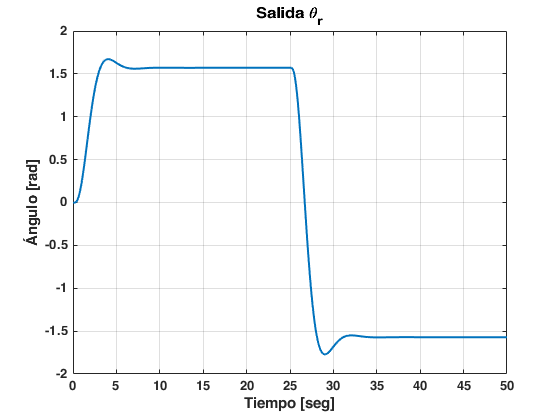

plot(t,theta,'LineWidth',1.5)
xlabel('Tiempo [seg]')
ylabel('Ángulo [rad]')
title('Salida \theta_r')
grid

Junto con la salida del ángulo del motor, también se pueden visualizar la corriente de armadura y la acción de control.

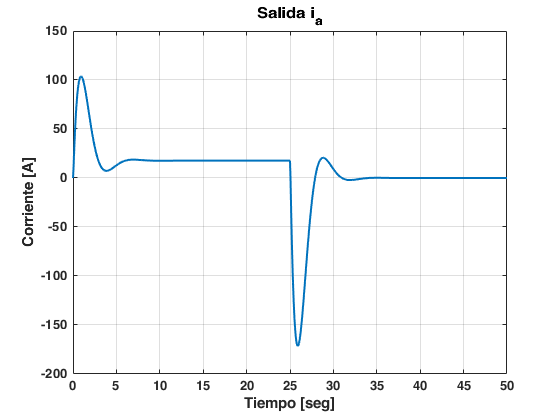

plot(t,ia,'LineWidth',1.5)
xlabel('Tiempo [seg]')
ylabel('Corriente [A]')
title('Salida i_a')
grid

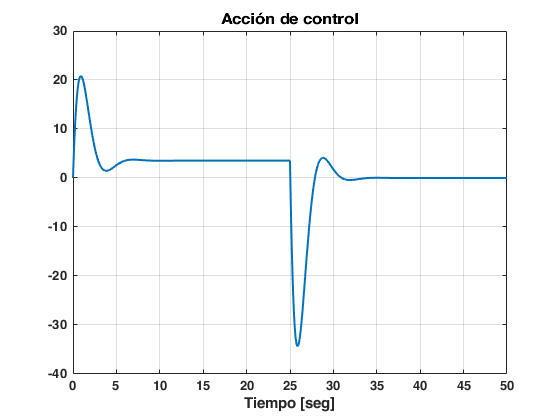

plot(t,u,'LineWidth',1.5)
xlabel('Tiempo [seg]')
title('Acción de control')
grid

Ahora, se plantea el observador. Se introducen las matrices que hacen referencia al sistema observador partiendo el original.

Ao = A'
Bo = C'
Co = B'
Qo = diag([1 0.01 0.01])
Ro = 10;
Ko = lqr(Ao,Bo,Qo,Ro)

Luego, se debe hacer una simulación del observador. Para ello lo siguiente, nuevamente, el procedimiento es el mismo que se aplicó anteriormente, por ello se obvian los comentarios.